## Plotting Vectors

This code sets up the interaction.

load data
data

data =     0.5300    0.5300    4.0753    0.5000
    1.7800    1.7800    6.6678    2.1328
    0.8600    0.8600    1.5177    3.6852
    1.6000    1.6000    3.6357    8.5389
    3.0000    3.0000    4.7243   10.1570
    6.1100    6.1100    9.0698    2.8739
    2.5400    2.5400    5.3002    4.4508


sample = data(:,1);
sample

sample =     0.5300
    1.7800
    0.8600
    1.6000
    3.0000
    6.1100
    2.5400


density = data(:,2);
density

density =     0.5300
    1.7800
    0.8600
    1.6000
    3.0000
    6.1100
    2.5400


v1 = data(:,3);
v1

v1 =     4.0753
    6.6678
    1.5177
    3.6357
    4.7243
    9.0698
    5.3002


v2 = data(:,4);
v2

v2 =     0.5000
    2.1328
    3.6852
    8.5389
   10.1570
    2.8739
    4.4508


mass1 = density.*v1;
mass1

mass1 =     2.1599
   11.8687
    1.3052
    5.8171
   14.1729
   55.4165
   13.4625


mass2 = density.*v2;
mass2

mass2 =     0.2650
    3.7964
    3.1693
   13.6622
   30.4710
   17.5595
   11.3050


**Task 1**		

You can plot two vectors of the same length against each other using the `plot` function.

`plot``(``x``,``y``)`

**Task**

Create a plot with `sample` on the *x*-axis and `mass1` on the *y*-axis.

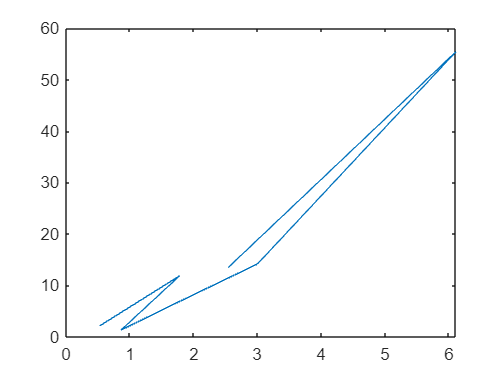

plot(sample, mass1)

**Task 2**

You can specify the color, line style, and marker of a plot by using different symbols in double quotes as another input to the `plot` function.

`plot``(``x``,``y``,``"r--o"``)`

The command plots a red (`r`) dashed (`--`) line with circle (`o`) markers.  You can learn more about the available symbols in the [Line Specification](https://www.mathworks.com/help/matlab/ref/plot.html#btzitot_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8) documentation.

**Task**

Plot `mass2` (*y*-axis) against `sample` (*x*-axis). Use red (`r`) star (`*`) markers and no line in your plot.

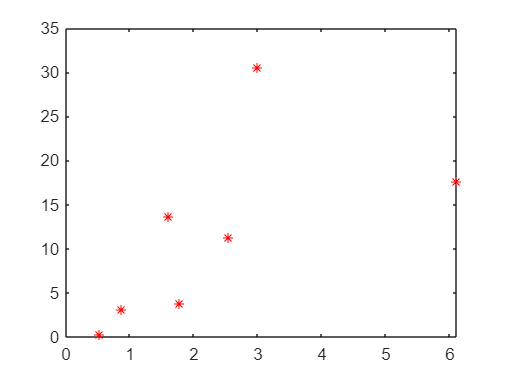

plot(sample, mass2, "r*")

**Task 3**

Notice that each `plot` command created a separate plot. You can plot one line on top of another in the same axes by using the `hold ``on` command.

`plot(x1,y1)`

`hold ``on`

`plot(x2,y2)`

**Task**

Enter the `hold ``on` command.

Then plot `mass1` (*y*-axis) against `sample` (*x*-axis) with black (`k`) square (`s`) markers and no line.

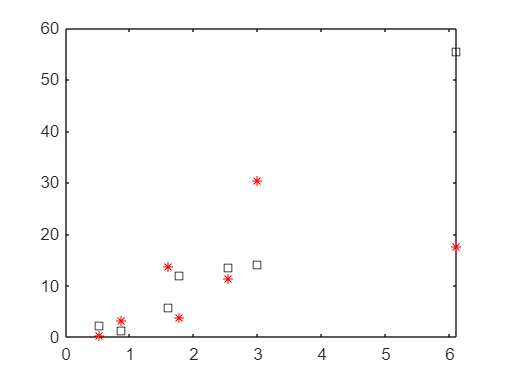

hold on
plot(sample,mass1,"ks")

**Task 4**

While the hold state is on, plots continue to appear  on the same axes. To return to the default plot behavior, where each  plot appears on its own axes, enter `hold ``off`.

**Task**

Enter the `hold ``off` command.

hold off

**Task 5**

When you plot a single vector by itself, MATLAB uses the vector values as the *y*-axis data and sets the *x*-axis data to the range of `1` to `n` (the number of elements in the vector).

`plot``(``y``)`

**Task**

Plot the vector `v1`.

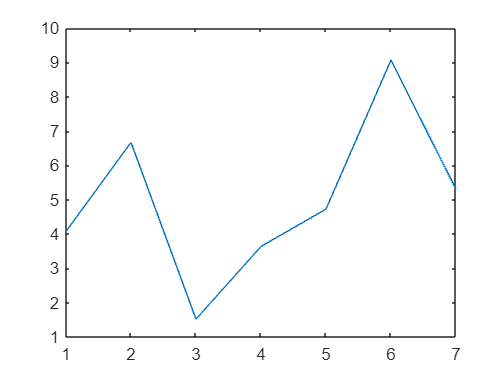

plot(v1)

**Task 6**

The `plot` function accepts optional additional inputs consisting of a property name and an associated value.

`plot``(``y``,``"LineWidth"``,``5``)`

The command plots a heavy line.  You can learn more about available properties in the [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html) documentation.

**Task**

Plot `v1` with a line width of `3`.

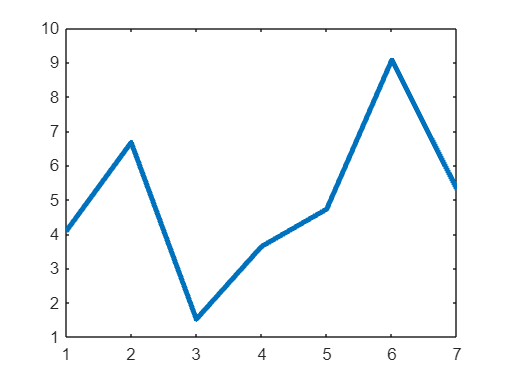

plot(v1,"Linewidth", 3)

**Task 7**

You can provide additional inputs to the `plot` function after the line specification.

`plot``(``x``,``y``,``"ro-"``,``"LineWidth"``,``5``)`

**Task**

Plot `v1` (*y*-axis) against `sample` (*x*-axis) with red (`r`) circle (`o`) markers and a solid line (`-`). Use a line width of `4`.

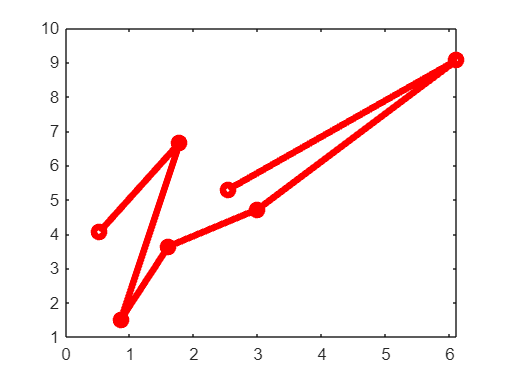

plot(sample, v1, "r-o", "LineWidth", 4)

**Further Practice**

The `plot` function creates lines. There are many other plotting functions in MATLAB. You can see an extensive list in the [MATLAB Plot Gallery](https://www.mathworks.com/products/matlab/plot-gallery.html). 

 Each plot has different customization options. Try creating a histogram of `density` with the `histogram` function. Set the `FaceColor` property to yellow (`"y"`).

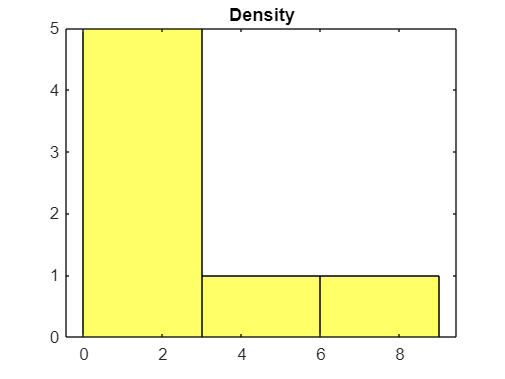

histogram(density, "FaceColor","y")
title("Density")